function analyze(window, overlap, data_o, data_c)
    %% データの分割
    cfg = [];
    cfg.showcallinfo = 'no';
    cfg.length = window; % 2秒の時間窓
    cfg.overlap = overlap; % 時間窓のオーバーラップの割合 (この場合2秒*0.5=1秒)
    data_o_crop = ft_redefinetrial(cfg, data_o);
    data_c_crop = ft_redefinetrial(cfg, data_c);
    %% FFT
    cfg = [];
    cfg.showcallinfo = 'no';
    cfg.method = 'mtmfft';
    cfg.taper = 'hanning';
    cfg.output = 'pow';
    FFT_o = ft_freqanalysis(cfg, data_o_crop);
    FFT_c = ft_freqanalysis(cfg, data_c_crop);
    
    cfg = [];
    cfg.channel = {'MEGGRAD'};
    cfg.combinemethod = 'sum';
    FFT_o_cmb = ft_combineplanar(cfg, FFT_o);
    FFT_c_cmb = ft_combineplanar(cfg, FFT_c);
    
    %[tmp, index] = sort(mean(FFT_o_cmb.powspctrm(:,8<FFT_o_cmb.freq&FFT_o_cmb.freq<13).'), 'descend');
    %Target_ch_o=index(1:10);
    %[tmp, index] = sort(mean(FFT_c_cmb.powspctrm(:,8<FFT_c_cmb.freq&FFT_c_cmb.freq<13).'), 'descend');
    %Target_ch_c=index(1:10);
    Target_ch_o=[72 79	78	74	62	77	90	71	73	75];
    Target_ch_c=[78	77	75	79	72	74	69	76	90	71];
    
    
    %% 等磁界線図のためのパラメータ設定
    cfg = [];
    cfg.showcallinfo = 'no';
    cfg.marker = 'on'; % センサの位置を表示
    cfg.layout = 'neuromag306cmb'; % 今回のデータのMEGシステムを指定
    cfg.xlim = [8 13]; % 8-13 Hzの平均パワーをプロット
    cfg.colorbar = 'yes'; % スケールバーを表示
    cfg.figure = 'gcf';
    cfg.highlight = 'on'; % スペクトル計算に用いたセンサをハイライト
    cfg.highlightcolor = [1 0 0]; % ハイライトの色を赤に設定
    %% 上段左に開眼時，右に閉眼時の等磁界線図をプロット
    figure;
    subplot(2,2,1);
    cfg.highlightchannel = Target_ch_o;
    ft_topoplotTFR(cfg, FFT_o_cmb);
    title('Open')
    subplot(2,2,2);
    cfg.highlightchannel = Target_ch_c;
    ft_topoplotTFR(cfg, FFT_c_cmb);
    title('Close');
    %% 選択されたセンサにわたって平均したパワースペクトルを描画
    aveFFT_o = mean(FFT_o_cmb.powspctrm(Target_ch_o,:))*10^26; % [T 2 /m 2 Hz] -> [fT 2 /cm 2 Hz]
    aveFFT_c = mean(FFT_c_cmb.powspctrm(Target_ch_c,:))*10^26; % [T 2 /m 2 Hz] -> [fT2 /cm 2 Hz]
    subplot(2,1,2)
    semilogy(FFT_o.freq, aveFFT_o,'Color',[0,135,255]/255,'LineWidth', 2);
    hold on;
    semilogy(FFT_c.freq, aveFFT_c,'Color',[255,42,99]/255,'LineWidth', 2);
    xlim([1 40]);
    legend('Open', 'Close')
    xlabel('Frequency [Hz]');
    ylabel('Power [fT^2 /cm^2 Hz]');
    
    window
    overlap
    'Maximam power and index of open eyes'
    [power, freq] = max(aveFFT_o(8<FFT_o_cmb.freq&FFT_o_cmb.freq<13));
    power
    freq = FFT_o_cmb.freq(find((8<FFT_o_cmb.freq&FFT_o_cmb.freq<13),1)+freq)
    'Maximam power and index of closed eyes'
    [power, freq] = max(aveFFT_c(8<FFT_c_cmb.freq&FFT_c_cmb.freq<13));
    power
    freq = FFT_c_cmb.freq(find((8<FFT_c_cmb.freq&FFT_c_cmb.freq<13),1)+freq)
end

%% データの読み込み
sub = 10; % 被験者の指定
filename = ['../../../materials/alpha_data_tsss/' 'sub' num2str(sub) '_alpha_data_tsss'];
dummy = ['load ' filename ' data_*'];
eval(dummy);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 174 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 174/174 nfft: 2000 samples, datalength: 2000 samples, 1 tapers

the input is raw data with 204 channels and 174 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 174/174 nfft: 2000 samples, datalength: 2000 samples, 1 tapers

the input is freq data with 204 channels, 1001 frequencybins and no timebins


 In ft_checkconfig at line 130
 In ft_combineplanar at line 81

the call to "ft_combineplanar" took 0 seconds
the input is freq data with 204 channels, 1001 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds
appending .lay to layout file
reading layout from file neuromag306cmb.lay
appending .lay to layout file
reading layout from file neuromag306cmb.lay


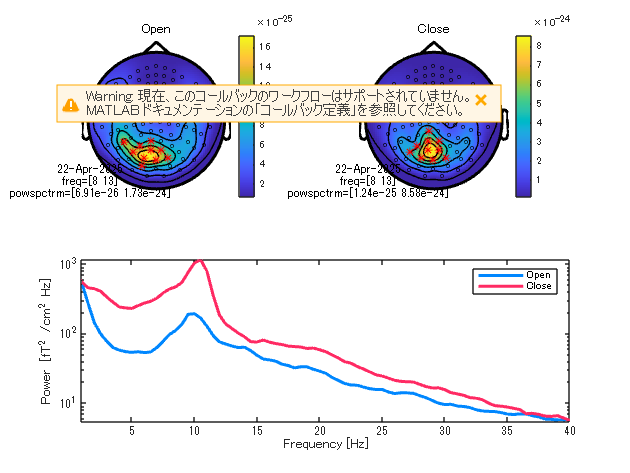

window = 2

overlap = 0.5000

ans = 'Maximam power and index of open eyes'

power = 191.9748

freq = 10.5000

ans = 'Maximam power and index of closed eyes'

power = 1.1476e+03

freq = 11

analyze(2,0.5, data_o, data_c);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 30 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 30/30 nfft: 10000 samples, datalength: 10000 samples, 1 tapers

the input is raw data with 204 channels and 30 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 30/30 nfft: 10000 samples, datalength: 10000 samples, 1 tapers

the input is freq data with 204 channels, 5001 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds
the input is freq data with 204 channels, 5001 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds
appending .lay to layout file
reading layout from file neuromag306cmb.lay
appending .lay to layout file
reading layout from file neuromag306cmb.lay


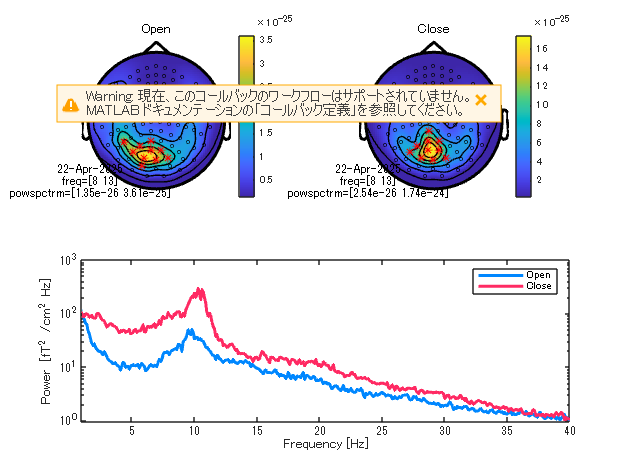

window = 10

overlap = 0.5000

ans = 'Maximam power and index of open eyes'

power = 49.3785

freq = 9.9000

ans = 'Maximam power and index of closed eyes'

power = 293.6684

freq = 10.4000

analyze(10,0.5, data_o, data_c);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 354 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 354/354 nfft: 1000 samples, datalength: 1000 samples, 1 tapers

the input is raw data with 204 channels and 354 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 354/354 nfft: 1000 samples, datalength: 1000 samples, 1 tapers

the input is freq data with 204 channels, 501 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds
the input is freq data with 204 channels, 501 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds
appending .lay to layout file
reading layout from file neuromag306cmb.lay
appending .lay to layout file
reading layout from file neuromag306cmb.lay


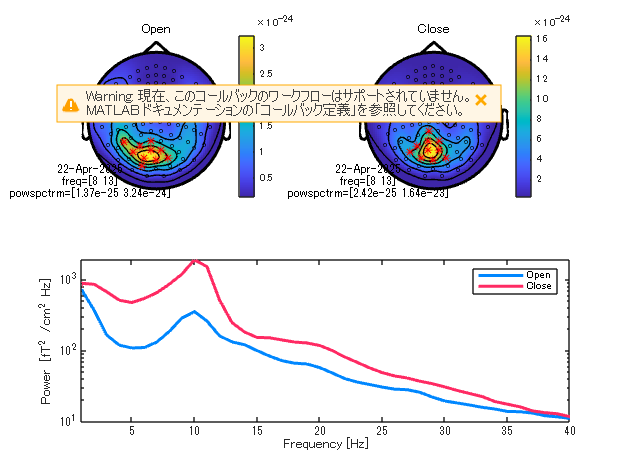

window = 1

overlap = 0.5000

ans = 'Maximam power and index of open eyes'

power = 352.1814

freq = 11

ans = 'Maximam power and index of closed eyes'

power = 1.8937e+03

freq = 11

analyze(1,0.5, data_o, data_c);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 96 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 96/96 nfft: 2000 samples, datalength: 2000 samples, 1 tapers

the input is raw data with 204 channels and 96 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 96/96 nfft: 2000 samples, datalength: 2000 samples, 1 tapers

the input is freq data with 204 channels, 1001 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds
the input is freq data with 204 channels, 1001 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds
appending .lay to layout file
reading layout from file neuromag306cmb.lay
appending .lay to layout file
reading layout from file neuromag306cmb.lay


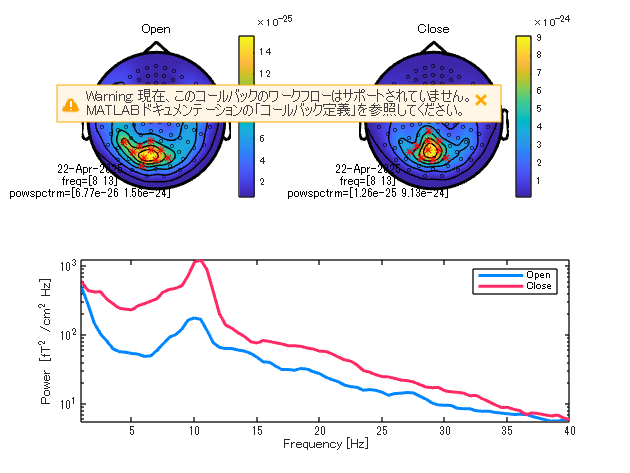

window = 2

overlap = 0.1000

ans = 'Maximam power and index of open eyes'

power = 174.5765

freq = 10.5000

ans = 'Maximam power and index of closed eyes'

power = 1.2204e+03

freq = 11

analyze(2,0.1, data_o, data_c);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 846 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 846/846 nfft: 2000 samples, datalength: 2000 samples, 1 tapers

the input is raw data with 204 channels and 846 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 846/846 nfft: 2000 samples, datalength: 2000 samples, 1 tapers

the input is freq data with 204 channels, 1001 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds
the input is freq data with 204 channels, 1001 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds
appending .lay to layout file
reading layout from file neuromag306cmb.lay
appending .lay to layout file
reading layout from file neuromag306cmb.lay


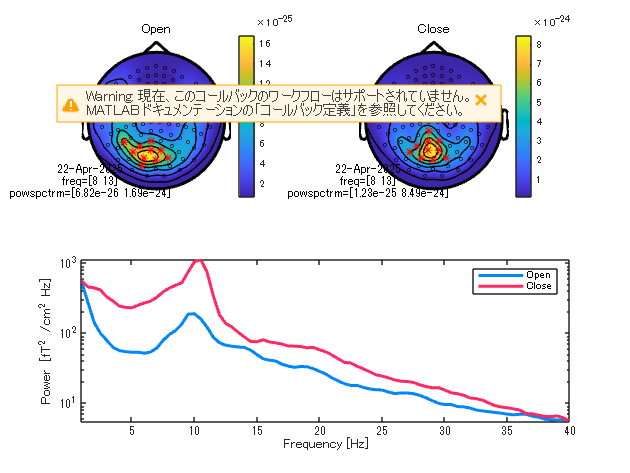

window = 2

overlap = 0.9000

ans = 'Maximam power and index of open eyes'

power = 187.9758

freq = 10.5000

ans = 'Maximam power and index of closed eyes'

power = 1.1114e+03

freq = 11

analyze(2,0.9, data_o, data_c);